Firstly, let's set the parameters for our project, based on the .pdf file in Canvas.

% Simulation time
t0 = 0;              % start time [days]
tf = 29;             % end time [days]
dt = 0.1;            % time resolution [days]
tspan = t0:dt:tf;    % time vector

% Initial Conditions (define separately for clarity)
T0 = 49.0497;   % Initial tumor volume [mm^3]
C0 = 0.171;     % Initial chemo drug concentration [mg/ml]

%% Tumor and Drug Parameters
C_M   = 1e4;           % Carrying capacity of tumor cells [mm^3]
d_c   = 0.1030;        % Natural death rate of tumor cells [/day]
b     = 0.1685;        % Death rate due to chemotherapy [/day]
lambda_ce = 0.4579;    % Tumor cell proliferation rate [/day]
d_d   = 0.1825;        % Clearance rate of chemotherapy drug [/day]
b_k   = 1.0839e-6;     % Drug clearance due to binding [mg/ml.day.mm^3]

%% Endothelial (Vascular) Parameters
E_thres = 4.5;         % Hypoxia threshold [mm^3]
lambda_e = 0.03;       % Endothelial proliferation rate [/day]
E_M   = 10;            % Carrying capacity of endothelial cells [mm^3]
d_e   = 0.05;          % Endothelial cell death rate [/day]

%% VEGF and Anti-VEGF Parameters
d_v   = 0.1;           % Natural decay rate of VEGF [/day]
d_b   = 0.005;         % Clearance rate of anti-VEGF drug [/day]
lambda_v0 = 1e-3;      % Baseline VEGF secretion rate [mg/ml.day.mm^3]
k     = 5;             % VEGF-induced endothelial proliferation [/day]
mu_B  = 10;            % VEGF removal when binding anti-VEGF [ml/day.mg]
mu_Bk = 0.15;          % Anti-VEGF clearance via binding [ml/day.mg]

%% Therapy Dosing Ranges (for future design or sensitivity analysis)
dose_chemo_range   = [0.002, 0.05];   % Chemotherapy dose [mg/ml]
dose_antiVEGF_range = [0.003, 0.07];  % Anti-VEGF dose [mg/ml]

% Add placeholders for future variables like VEGF, endothelial cells, etc.
E0 = 1.75;      % Initial endothelial density [mm^3] (within the 0.5–3 range)
V0 = 1;       % Initial VEGF [mg/ml] (within 0.5-1.5 range)
A0 = 0.213;      % Initial anti-VEGF drug concentration [mg/ml]

%% Matrix of coefficients with patients. Each row is a parameter, each column is a patient (by number in the .docx file)
% Order of rows:
% 1. Proliferation rate of the tumor cells
% 2. Carrying capacity tumor cells
% 3. Baseline VEGF secretion by tumor cells
% 4. Clearance of drugs by the kidneys


patients_coeffs = [
    1.20, 0.85, 1.50, 0.70, 1.05;  % Proliferation rate
    0.90, 0.80, 1.35, 1.05, 1.10;  % Carrying capacity
    1.50, 1.20, 0.90, 1.10, 0.80;  % VEGF secretion
    0.70, 1.10, 1.50, 0.85, 1.20   % Drug clearance
];

The Growth **model declaration **and** initial **results, with only **initial drugs dosing**.

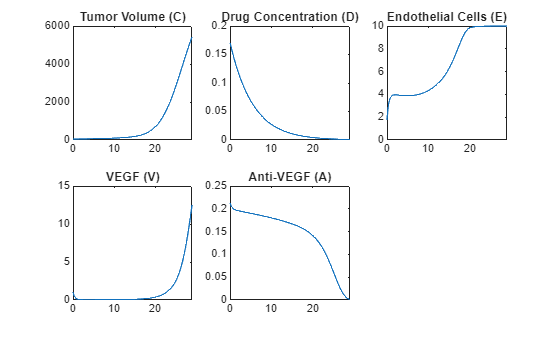

x0_extended = [T0; C0; E0; V0; A0];

params_extended = struct( ...
    'd_c', d_c, ...
    'b', b, ...
    'lambda_ce', lambda_ce, ...
    'd_d', d_d, ...
    'b_k', b_k, ...
    'c_M', C_M, ...
    'lambda_e', lambda_e, ...
    'd_e', d_e, ...
    'E_M', E_M, ...
    'd_v', d_v, ...
    'lambda_v0', lambda_v0, ...
    'd_b', d_b, ...
    'k', k, ...
    'mu_B', mu_B, ...
    'mu_Bk', mu_Bk ...
);

% Run simulation
[T1, Y1] = ode15s(@(t,y) Model_extended(t,y,params_extended), tspan, x0_extended);

% Plotting the variables of the extendedn model

figure;
subplot(2,3,1); plot(T1, Y1(:,1)); title('Tumor Volume (C)');
subplot(2,3,2); plot(T1, Y1(:,2)); title('Drug Concentration (D)');
subplot(2,3,3); plot(T1, Y1(:,3)); title('Endothelial Cells (E)');
subplot(2,3,4); plot(T1, Y1(:,4)); title('VEGF (V)');
subplot(2,3,5); plot(T1, Y1(:,5)); title('Anti-VEGF (A)');

The comparison between **no VEGF** and **yes VEGF/anti-VEGF drug**.

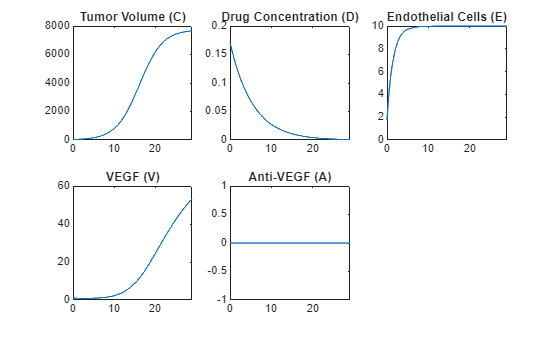

% Initial conditions (A0 = 0)
x0_no_anti_vegf = [T0; C0; E0; V0; 0];

% Run simulation using original Model_logistic (no VEGF, no E, no A)
[T2, Y2] = ode15s(@(t, y) Model_extended(t, y, params_extended), tspan, x0_no_anti_vegf);

% Plotting the variables of the extendedn model without anti-VEGF

figure;
subplot(2,3,1); plot(T2, Y2(:,1)); title('Tumor Volume (C)');
subplot(2,3,2); plot(T2, Y2(:,2)); title('Drug Concentration (D)');
subplot(2,3,3); plot(T2, Y2(:,3)); title('Endothelial Cells (E)');
subplot(2,3,4); plot(T2, Y2(:,4)); title('VEGF (V)');
subplot(2,3,5); plot(T2, Y2(:,5)); title('Anti-VEGF (A)');

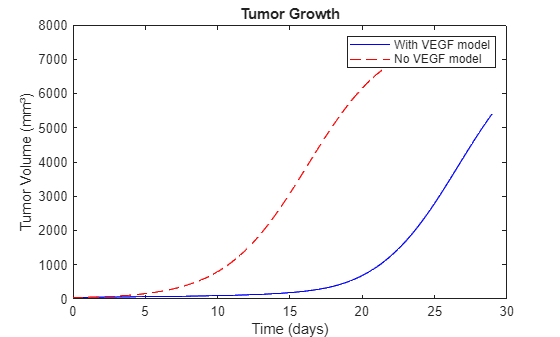


% Plotting Tumor volume (C) for difference between models

figure;
plot(T1, Y1(:,1), 'b-', T2, Y2(:,1), 'r--');
xlabel('Time (days)');
ylabel('Tumor Volume (mm³)');
title('Tumor Growth');
legend('With VEGF model', 'No VEGF model');

The models playing with **continuous drugs dosing for both **(Work in progress).

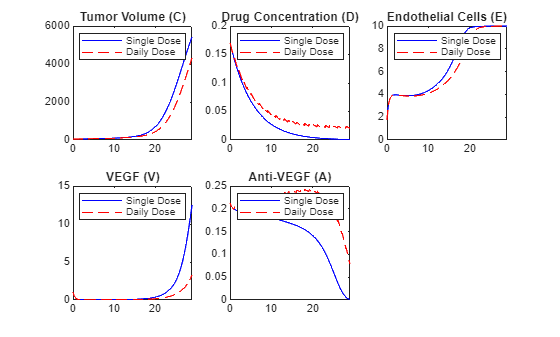

x0_everyday_injection = [T0; C0; E0; V0; A0];

%Computing the ODE for the 1st day

[T3, Y3] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:0.1:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day

for i = 1:1:tf-1
    C_end = Y3(end,1);
    D_end = Y3(end,2) + 0.004; % inject chemotherapy daily
    E_end = Y3(end,3);
    V_end = Y3(end,4);
    A_end = Y3(end,5) + 0.005;  % inject anti-VEGF daily
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T3(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T3 = [T3; Tstep(2:end)];
    Y3 = [Y3; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T3, Y3(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T3, Y3(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T3, Y3(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T3, Y3(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T3, Y3(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

The models playing with **continuous drugs dosing only for Anti-VEGF**.

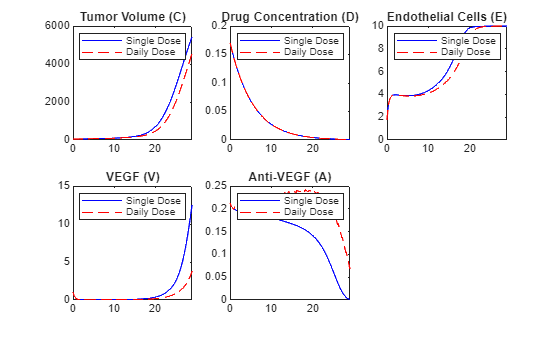

x0_everyday_injection = [T0; C0; E0; V0; A0];

%Computing the ODE for the 1st day

[T4, Y4] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:0.1:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day

for i = 1:1:tf-1
    C_end = Y4(end,1);
    D_end = Y4(end,2);
    E_end = Y4(end,3);
    V_end = Y4(end,4);
    A_end = Y4(end,5) + 0.005;  % inject anti-VEGF daily
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T4(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T4 = [T4; Tstep(2:end)];
    Y4 = [Y4; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T4, Y4(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T4, Y4(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T4, Y4(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T4, Y4(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T4, Y4(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

The models playing with **continuous drugs dosing only for the Chemotherapeutic**.

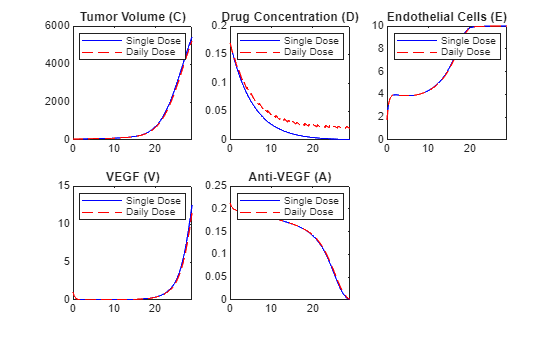

x0_everyday_injection = [T0; C0; E0; V0; A0];

%Computing the ODE for the 1st day

[T5, Y5] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:0.1:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day

for i = 1:1:tf-1
    C_end = Y5(end,1);
    D_end = Y5(end,2) + 0.004; % inject chemotherapy daily
    E_end = Y5(end,3);
    V_end = Y5(end,4);
    A_end = Y5(end,5);  
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T5(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T5 = [T5; Tstep(2:end)];
    Y5 = [Y5; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T5, Y5(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T5, Y5(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T5, Y5(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T5, Y5(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T5, Y5(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

**Comparing** all models

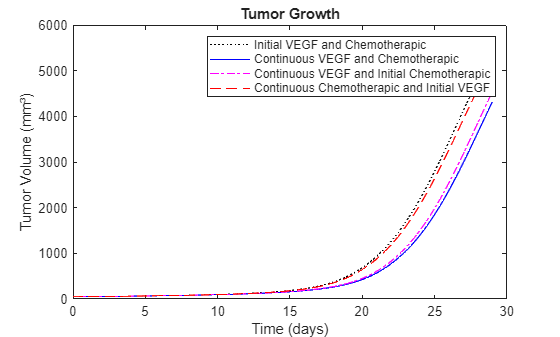


figure;
plot(T1, Y1(:,1), 'k:', ...                                    % Both parameters initial only
     T3, Y3(:,1), 'b-', ...                                    % Continuous VEGF and Chemotherapic model
     T4, Y4(:,1), 'm-.', ...                                   % Continuous VEGF and Initial Chemotherapic model
     T5, Y5(:,1), 'r--');                                      % Continuous Chemotherapic, Initial VEGF model
xlabel('Time (days)');
ylabel('Tumor Volume (mm³)');
title('Tumor Growth');
legend('Initial VEGF and Chemotherapic', ...
       'Continuous VEGF and Chemotherapic', ...
       'Continuous VEGF and Initial Chemotherapic', ...
       'Continuous Chemotherapic and Initial VEGF');

The function needed to configure the model and calculate the tumour.

function dYdt = Model_extended(t, Y, params)

%Unpacking variables

C = Y(1);  % Tumor
D = Y(2);  % Drug
E = Y(3);  % Endothelial cells
V = Y(4);  % VEGF
A = Y(5);  % Anti-VEGF

%Unpacking the struct
d_c = params.d_c;
b = params.b;
lambda_ce = params.lambda_ce;
d_d = params.d_d;
b_k = params.b_k;
c_M = params.c_M;

lambda_e = params.lambda_e;
d_e = params.d_e;
E_M = params.E_M;

d_v = params.d_v;
lambda_v0 = params.lambda_v0;
d_b = params.d_b;
k = params.k;
mu_B = params.mu_B;
mu_Bk = params.mu_Bk;


%%Equations (not sure about them). No hypoxia is (yet) used.

dCdt = lambda_ce * C * (1 - C / c_M) * (E / E_M) - d_c * C - b * C * D * (E / E_M); % Using logistic model for the tumour growth, adding dependency on E
dDdt = -d_d * D - b_k * C * D * (E / E_M); % (E / E_M) adds dependency on the number of the endothelial cells and vascularisation.
%dEdt = lambda_e * k * V * (1 - E / E_M) - d_e * E; % Again, logistic for the endothelial cells growth, without dependency on C
dEdt = lambda_e * k * C * V * (1 - E / E_M) - d_e * E; % Again, logistic for the endothelial cells growth, including dependency on C
dVdt = lambda_v0 * C - d_v * V - mu_B * A * V; %Hypoxia would be added here, naturally
dAdt = -d_b * A - mu_Bk * A * V;


% Return
dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];

end

